clear
clc
%format long

[x,y] = RungeKutta_sistema('pvi_sis',1,1.9,20,[-1 -1 -2]);
[x1,y1] = runge_kutta('pvi_sis',1,1.9,20,[-1 -1 -2]);

solex=1./(x-2);

error=abs(solex-y(:,1));

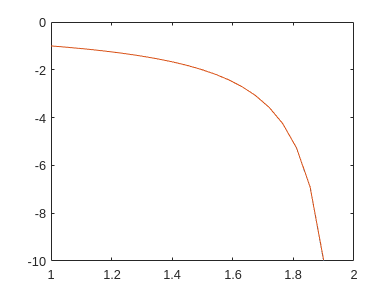

plot(x,solex)
hold on
plot(x,y1(:,1))
hold off

[x1,y1] = runge_kutta('PVI',0,2,10,[3 1 3 3]);

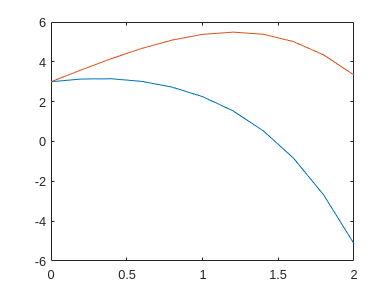

plot(x1,y1(:,1))
hold on
plot(x1,y1(:,3))
hold off

[x1,y1] = RungeKutta_sistema('PVI',0, 2, 10, [3 1 3 3]);
plot(x1,y1(:,1))
hold on
plot(x1,y1(:,3))
hold off

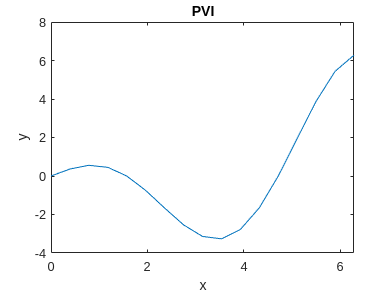

clear

[x,y] = RungeKutta_sistema('pvi_sis2',0,2*pi,16,[0 1]);
plot(x,y(:,1))
xlabel("x")
ylabel("y")
title("PVI")

% Calculando el orden de convergencia

n=0:10;
N=16*2.^n;

for j=2:length(n)-1
    disp(N(j))
    [x,y2] = RungeKutta_sistema('pvi_sis2',0,2*pi,N(j),[0 1]);
    error(j-1) = norm(y(:,1)-y2(1:2:end,1));
    disp(error(j-1))
    y = y2;
end

    32



   0.007455504088416



    64



     6.389815136284894e-04



   128



     5.556391007661805e-05



   256



     4.870260315095321e-06



   512



     4.286542081445422e-07



        1024



     3.780731409834595e-08



        2048



     3.338228679847957e-09



        4096



     2.947471057903721e-10



        8192



     2.622157894199255e-11




orden_convergencia =log2(error(1:end-1)./error(2:end));
